# Лабораторна робота. Виділення контурів (перепадів яскравості) зі згладжуванням поверхнею другого порядку

Краснопір Тимур, ІПС-32

## Вступ

Для того, аби отримати найкращий результат виділення контурів зображення, до зображення спочатку треба застосувати згладження. Згладження зображення зменшує чутливість до шуму. А це, в свою чергу, зменшує кількість фіктивних контурів, тобто контурів, отриманих з шуму.

Нижче наведено покроковий опис алгоритму виділення контурів зі згладжуванням поверхнею другого порядку. Цей алгоритм згладжує вихідне зображення поверхнею другого порядку, а вже потім виділяє контури зображення.

## Побудова апроксимуючої поверхні другого порядку

Побудуємо апроксимуючу поверхню другого порядку.

% f(x, y) is an approximating surface of the second order
syms f(x, y) a b c alpha beta gamma
f(x, y) = a*x^2 + b*y^2 + c*x*y + alpha*x + beta*y + gamma;

Для побудови апроксимуючої поверхні другого порядку використаємо метод найменших квадратів. При пошуку невідомих коефіцієнтів (`a`, `b`, `c`, `alpha`, `beta` та `gamma`) будемо мінімізувати квадратичну похибку. Квадратична похибка наведена нижче.

% g(x, y) is a window
syms g(x, y)
epsilon = (f(x-1, y-1) - g(x-1, y-1))^2 + (f(x-1, y) - g(x-1, y))^2 + (f(x-1, y+1) - g(x-1, y+1))^2 ... 
    + (f(x, y-1) - g(x, y-1))^2 + (f(x, y) - g(x, y))^2 + (f(x, y+1) - g(x, y+1))^2 ... 
    + (f(x+1, y-1) - g(x+1, y-1))^2 + (f(x+1, y) - g(x+1, y))^2 + (f(x+1, y+1) - g(x+1, y+1))^2;

Наступну систему лінійних алгебраїчних рівнянь відносно невідомих коефіцієнтів `a`, `b`, `c`, `alpha`, `beta` та `gamma` отримаємо з необхідних умов мінімуму квадратичної похибки.

eqn1 = diff(epsilon, a) == 0;
eqn2 = diff(epsilon, b) == 0;
eqn3 = diff(epsilon, c) == 0;
eqn4 = diff(epsilon, alpha) == 0;
eqn5 = diff(epsilon, beta) == 0;
eqn6 = diff(epsilon, gamma) == 0;

Матриця A цієї системи лінійних алгебраїчних рівнянь наведена нижче.

[A, B] = equationsToMatrix([eqn1, eqn2, eqn3, eqn4, eqn5, eqn6], [a, b, c, alpha, beta, gamma]);
A

Розв'яжемо наведену вище систему лінійних алгебраїчних рівнянь.

coefficients = solve([eqn1, eqn2, eqn3, eqn4, eqn5, eqn6], [a, b, c, alpha, beta, gamma]);

Отримаємо наступний розв'язок цієї системи лінійних алгебраїчних рівнянь.

coefficients.a

$$ans = \frac{g\left(x-1,y-1\right)}{6}+\frac{g\left(x-1,y+1\right)}{6}+\frac{g\left(x+1,y-1\right)}{6}+\frac{g\left(x+1,y+1\right)}{6}-\frac{g\left(x,y\right)}{3}-\frac{g\left(x,y-1\right)}{3}-\frac{g\left(x,y+1\right)}{3}+\frac{g\left(x-1,y\right)}{6}+\frac{g\left(x+1,y\right)}{6}$$

coefficients.b

$$ans = \frac{g\left(x-1,y-1\right)}{6}+\frac{g\left(x-1,y+1\right)}{6}+\frac{g\left(x+1,y-1\right)}{6}+\frac{g\left(x+1,y+1\right)}{6}-\frac{g\left(x,y\right)}{3}+\frac{g\left(x,y-1\right)}{6}+\frac{g\left(x,y+1\right)}{6}-\frac{g\left(x-1,y\right)}{3}-\frac{g\left(x+1,y\right)}{3}$$

coefficients.c

$$ans = \frac{g\left(x-1,y-1\right)}{4}-\frac{g\left(x-1,y+1\right)}{4}-\frac{g\left(x+1,y-1\right)}{4}+\frac{g\left(x+1,y+1\right)}{4}$$

coefficients.alpha

$$ans = \begin{array}{l} \frac{\sigma_{3}}{6}-\frac{\sigma_{2}}{6}-\frac{\sigma_{1}}{6}+\frac{\sigma_{4}}{6}+\frac{2\,x\,g\left(x,y\right)}{3}+\frac{2\,x\,g\left(x,y-1\right)}{3}+\frac{2\,x\,g\left(x,y+1\right)}{3}-\frac{x\,\sigma_{5}}{3}-\frac{x\,\sigma_{6}}{3}-\frac{\sigma_{5}}{6}+\frac{\sigma_{6}}{6}-\frac{x\,\sigma_{1}}{3}-\frac{x\,\sigma_{2}}{3}-\frac{x\,\sigma_{3}}{3}-\frac{x\,\sigma_{4}}{3}-\frac{y\,\sigma_{1}}{4}+\frac{y\,\sigma_{2}}{4}+\frac{y\,\sigma_{3}}{4}-\frac{y\,\sigma_{4}}{4}\\ \mathrm{where}\\ \sigma_{1}=g\left(x-1,y-1\right)\\ \sigma_{2}=g\left(x-1,y+1\right)\\ \sigma_{3}=g\left(x+1,y-1\right)\\ \sigma_{4}=g\left(x+1,y+1\right)\\ \sigma_{5}=g\left(x-1,y\right)\\ \sigma_{6}=g\left(x+1,y\right) \end{array}$$

coefficients.beta

$$ans = \begin{array}{l} \frac{\sigma_{2}}{6}-\frac{\sigma_{1}}{6}-\frac{\sigma_{3}}{6}+\frac{\sigma_{4}}{6}+\frac{2\,y\,g\left(x,y\right)}{3}-\frac{y\,\sigma_{5}}{3}-\frac{y\,\sigma_{6}}{3}+\frac{2\,y\,g\left(x-1,y\right)}{3}+\frac{2\,y\,g\left(x+1,y\right)}{3}-\frac{\sigma_{5}}{6}+\frac{\sigma_{6}}{6}-\frac{x\,\sigma_{1}}{4}+\frac{x\,\sigma_{2}}{4}+\frac{x\,\sigma_{3}}{4}-\frac{x\,\sigma_{4}}{4}-\frac{y\,\sigma_{1}}{3}-\frac{y\,\sigma_{2}}{3}-\frac{y\,\sigma_{3}}{3}-\frac{y\,\sigma_{4}}{3}\\ \mathrm{where}\\ \sigma_{1}=g\left(x-1,y-1\right)\\ \sigma_{2}=g\left(x-1,y+1\right)\\ \sigma_{3}=g\left(x+1,y-1\right)\\ \sigma_{4}=g\left(x+1,y+1\right)\\ \sigma_{5}=g\left(x,y-1\right)\\ \sigma_{6}=g\left(x,y+1\right) \end{array}$$

coefficients.gamma

$$ans = \begin{array}{l} \frac{x^{2}\,\sigma_{1}}{6}-\frac{\sigma_{2}}{9}-\frac{\sigma_{3}}{9}-\frac{\sigma_{4}}{9}-\frac{\sigma_{1}}{9}+\frac{x^{2}\,\sigma_{2}}{6}+\frac{x^{2}\,\sigma_{3}}{6}+\frac{x^{2}\,\sigma_{4}}{6}+\frac{y^{2}\,\sigma_{1}}{6}+\frac{y^{2}\,\sigma_{2}}{6}+\frac{y^{2}\,\sigma_{3}}{6}+\frac{y^{2}\,\sigma_{4}}{6}+\frac{5\,g\left(x,y\right)}{9}+\frac{x\,\sigma_{5}}{6}-\frac{x\,\sigma_{6}}{6}-\frac{x^{2}\,g\left(x,y\right)}{3}+\frac{y\,\sigma_{7}}{6}-\frac{y\,\sigma_{8}}{6}-\frac{y^{2}\,g\left(x,y\right)}{3}+\frac{2\,\sigma_{7}}{9}+\frac{2\,\sigma_{8}}{9}+\frac{2\,\sigma_{5}}{9}+\frac{2\,\sigma_{6}}{9}+\frac{x\,\sigma_{1}}{6}+\frac{x\,\sigma_{2}}{6}-\frac{x\,\sigma_{3}}{6}-\frac{x\,\sigma_{4}}{6}-\frac{x^{2}\,\sigma_{7}}{3}-\frac{x^{2}\,\sigma_{8}}{3}+\frac{x^{2}\,\sigma_{5}}{6}+\frac{x^{2}\,\sigma_{6}}{6}+\frac{y\,\sigma_{1}}{6}-\frac{y\,\sigma_{2}}{6}+\frac{y\,\sigma_{3}}{6}-\frac{y\,\sigma_{4}}{6}+\frac{y^{2}\,\sigma_{7}}{6}+\frac{y^{2}\,\sigma_{8}}{6}-\frac{y^{2}\,\sigma_{5}}{3}-\frac{y^{2}\,\sigma_{6}}{3}+\frac{x\,y\,\sigma_{1}}{4}-\frac{x\,y\,\sigma_{2}}{4}-\frac{x\,y\,\sigma_{3}}{4}+\frac{x\,y\,\sigma_{4}}{4}\\ \mathrm{where}\\ \sigma_{1}=g\left(x-1,y-1\right)\\ \sigma_{2}=g\left(x-1,y+1\right)\\ \sigma_{3}=g\left(x+1,y-1\right)\\ \sigma_{4}=g\left(x+1,y+1\right)\\ \sigma_{5}=g\left(x-1,y\right)\\ \sigma_{6}=g\left(x+1,y\right)\\ \sigma_{7}=g\left(x,y-1\right)\\ \sigma_{8}=g\left(x,y+1\right) \end{array}$$

## Модуль градієнта

Формула модуля градієнта наведена нижче.

% grad(x, y) is |grad(x, y)|
syms grad(x, y)
grad(x, y) = sqrt((2*(coefficients.a)*x + (coefficients.c)*y + coefficients.alpha)^2 ... 
    + (2*(coefficients.b)*y + (coefficients.c)*x + coefficients.beta)^2);

## Застосування алгоритму до зображення `cameraman.tif`

Зчитаємо зображення з графічного файлу `cameraman.tif`.

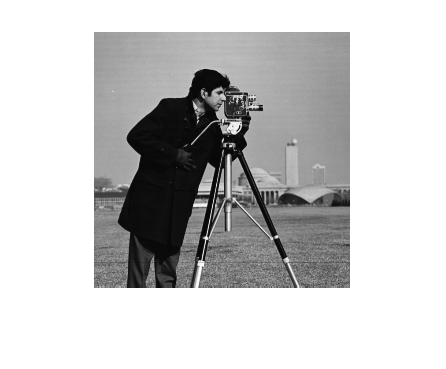

originalImage = imread('cameraman.tif');
imshow(originalImage);

originalImage = double(originalImage);

Створимо нове зображення, у яке запишемо результат.

resultImage = zeros(size(originalImage), class(originalImage));

Для кожної точки вихідного зображення `originalImage` обрахуємо модуль градієнта (за наведеної вище формулою). Запишемо отримані значення у нове зображення `resultImage`.

Нижче формула модуля градієнта записана після підстановки у цю формулу знайдених значень відповідних коефіцієнтів.

% x is a row, y is a column
for x = 2:(size(originalImage, 1) - 1)
    for y = 2:(size(originalImage, 2) - 1)
        % the statement below is equivalent to: resultImage(x, y) = grad(x, y);
        resultImage(x, y) = sqrt((originalImage(x - 1, y - 1)/6 - y*(originalImage(x - 1, y - 1)/4 ... 
                - originalImage(x - 1, y + 1)/4 - originalImage(x + 1, y - 1)/4 + originalImage(x + 1, y + 1)/4) ... 
                + originalImage(x - 1, y + 1)/6 - originalImage(x + 1, y - 1)/6 - originalImage(x + 1, y + 1)/6 ... 
                - x*(originalImage(x - 1, y - 1)/3 + originalImage(x - 1, y + 1)/3 + originalImage(x + 1, y - 1)/3 ... 
                + originalImage(x + 1, y + 1)/3 - (2*originalImage(x, y))/3 - (2*originalImage(x, y - 1))/3 ... 
                - (2*originalImage(x, y + 1))/3 + originalImage(x - 1, y)/3 + originalImage(x + 1, y)/3) ... 
                - (2*x*originalImage(x, y))/3 - (2*x*originalImage(x, y - 1))/3 - (2*x*originalImage(x, y + 1))/3 ... 
                + (x*originalImage(x - 1, y))/3 + (x*originalImage(x + 1, y))/3 + originalImage(x - 1, y)/6 ... 
                - originalImage(x + 1, y)/6 + (x*originalImage(x - 1, y - 1))/3 + (x*originalImage(x - 1, y + 1))/3 ... 
                + (x*originalImage(x + 1, y - 1))/3 + (x*originalImage(x + 1, y + 1))/3 + (y*originalImage(x - 1, y - 1))/4 ... 
                - (y*originalImage(x - 1, y + 1))/4 - (y*originalImage(x + 1, y - 1))/4 + (y*originalImage(x + 1, y + 1))/4)^2 ... 
                + (originalImage(x - 1, y - 1)/6 - x*(originalImage(x - 1, y - 1)/4 - originalImage(x - 1, y + 1)/4 ... 
                - originalImage(x + 1, y - 1)/4 + originalImage(x + 1, y + 1)/4) - originalImage(x - 1, y + 1)/6 ... 
                + originalImage(x + 1, y - 1)/6 - originalImage(x + 1, y + 1)/6 - y*(originalImage(x - 1, y - 1)/3 ... 
                + originalImage(x - 1, y + 1)/3 + originalImage(x + 1, y - 1)/3 + originalImage(x + 1, y + 1)/3 ... 
                - (2*originalImage(x, y))/3 + originalImage(x, y - 1)/3 + originalImage(x, y + 1)/3 ... 
                - (2*originalImage(x - 1, y))/3 - (2*originalImage(x + 1, y))/3) - (2*y*originalImage(x, y))/3 ... 
                + (y*originalImage(x, y - 1))/3 + (y*originalImage(x, y + 1))/3 - (2*y*originalImage(x - 1, y))/3 ... 
                - (2*y*originalImage(x + 1, y))/3 + originalImage(x, y - 1)/6 - originalImage(x, y + 1)/6 ... 
                + (x*originalImage(x - 1, y - 1))/4 - (x*originalImage(x - 1, y + 1))/4 - (x*originalImage(x + 1, y - 1))/4 ... 
                + (x*originalImage(x + 1, y + 1))/4 + (y*originalImage(x - 1, y - 1))/3 + (y*originalImage(x - 1, y + 1))/3 ... 
                + (y*originalImage(x + 1, y - 1))/3 + (y*originalImage(x + 1, y + 1))/3)^2);
    end
end

Результат застосування алгоритму до зображення `cameraman.tif `наведено нижче.

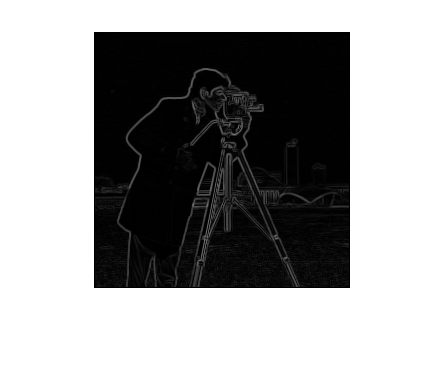

imshow(uint8(resultImage));

Результат у негативі наведено нижче.

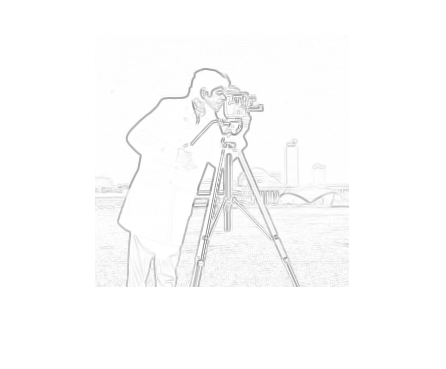

imshow(255 - uint8(resultImage)); % negative resultImage

## Визначення часу роботи програми

Загальний час (тобто з урахуванням часу на знаходження невідомих коефіцієнтів та формули модуля градієнта) роботи програми складає `0.7193 `секунди (визначено за допомогою функції `timeit`).

Але знаходження формули модуля градієнта (що включає знаходження невідомих коефіцієнтів) необхідно виконати лише один раз. А вже далі застосовувати цю формулу для виділення контурів того чи іншого зображення. Тобто при виділенні контурів того чи іншого зображення підставляти у цю формулу модуля градієнта конкретні значення з вікна та конкретні координати `x` та `y`.

Тому доцільно за загальний час роботи програми обрати час роботи функції `applyEdgeDetectionAlgorithm`, код якої наведено нижче. Тобто не враховувати час, що затрачено на знаходження формули модуля градієнта.

Нижче наведено час роботи функції `applyEdgeDetectionAlgorithm`  (час зазначено в секундах).

edgeDetectionAlgorithm = @() applyEdgeDetectionAlgorithm(originalImage);
time = timeit(edgeDetectionAlgorithm)

time = 0.0092

Код функції `applyEdgeDetectionAlgorithm `наведено нижче.

function resultImage = applyEdgeDetectionAlgorithm(originalImage)
    resultImage = zeros(size(originalImage), class(originalImage));
    % x is a row, y is a column
    for x = 2:(size(originalImage, 1) - 1)
        for y = 2:(size(originalImage, 2) - 1)
            % the statement below is equivalent to: resultImage(x, y) = grad(x, y);
            resultImage(x, y) = sqrt((originalImage(x - 1, y - 1)/6 - y*(originalImage(x - 1, y - 1)/4 ... 
                - originalImage(x - 1, y + 1)/4 - originalImage(x + 1, y - 1)/4 + originalImage(x + 1, y + 1)/4) ... 
                + originalImage(x - 1, y + 1)/6 - originalImage(x + 1, y - 1)/6 - originalImage(x + 1, y + 1)/6 ... 
                - x*(originalImage(x - 1, y - 1)/3 + originalImage(x - 1, y + 1)/3 + originalImage(x + 1, y - 1)/3 ... 
                + originalImage(x + 1, y + 1)/3 - (2*originalImage(x, y))/3 - (2*originalImage(x, y - 1))/3 ... 
                - (2*originalImage(x, y + 1))/3 + originalImage(x - 1, y)/3 + originalImage(x + 1, y)/3) ... 
                - (2*x*originalImage(x, y))/3 - (2*x*originalImage(x, y - 1))/3 - (2*x*originalImage(x, y + 1))/3 ... 
                + (x*originalImage(x - 1, y))/3 + (x*originalImage(x + 1, y))/3 + originalImage(x - 1, y)/6 ... 
                - originalImage(x + 1, y)/6 + (x*originalImage(x - 1, y - 1))/3 + (x*originalImage(x - 1, y + 1))/3 ... 
                + (x*originalImage(x + 1, y - 1))/3 + (x*originalImage(x + 1, y + 1))/3 + (y*originalImage(x - 1, y - 1))/4 ... 
                - (y*originalImage(x - 1, y + 1))/4 - (y*originalImage(x + 1, y - 1))/4 + (y*originalImage(x + 1, y + 1))/4)^2 ... 
                + (originalImage(x - 1, y - 1)/6 - x*(originalImage(x - 1, y - 1)/4 - originalImage(x - 1, y + 1)/4 ... 
                - originalImage(x + 1, y - 1)/4 + originalImage(x + 1, y + 1)/4) - originalImage(x - 1, y + 1)/6 ... 
                + originalImage(x + 1, y - 1)/6 - originalImage(x + 1, y + 1)/6 - y*(originalImage(x - 1, y - 1)/3 ... 
                + originalImage(x - 1, y + 1)/3 + originalImage(x + 1, y - 1)/3 + originalImage(x + 1, y + 1)/3 ... 
                - (2*originalImage(x, y))/3 + originalImage(x, y - 1)/3 + originalImage(x, y + 1)/3 ... 
                - (2*originalImage(x - 1, y))/3 - (2*originalImage(x + 1, y))/3) - (2*y*originalImage(x, y))/3 ... 
                + (y*originalImage(x, y - 1))/3 + (y*originalImage(x, y + 1))/3 - (2*y*originalImage(x - 1, y))/3 ... 
                - (2*y*originalImage(x + 1, y))/3 + originalImage(x, y - 1)/6 - originalImage(x, y + 1)/6 ... 
                + (x*originalImage(x - 1, y - 1))/4 - (x*originalImage(x - 1, y + 1))/4 - (x*originalImage(x + 1, y - 1))/4 ... 
                + (x*originalImage(x + 1, y + 1))/4 + (y*originalImage(x - 1, y - 1))/3 + (y*originalImage(x - 1, y + 1))/3 ... 
                + (y*originalImage(x + 1, y - 1))/3 + (y*originalImage(x + 1, y + 1))/3)^2);
        end
    end
end